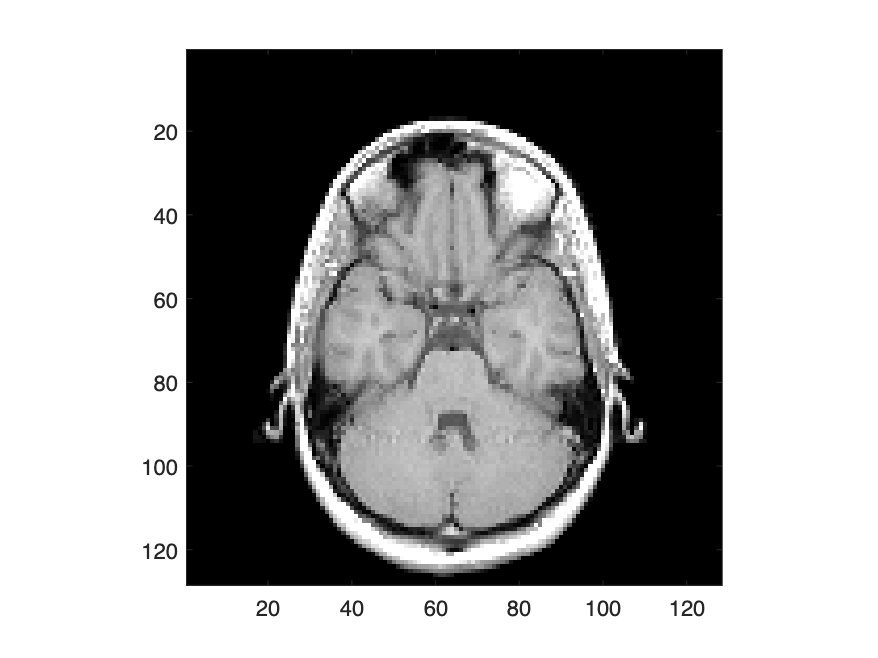

clear all; close all;
load mri
D = squeeze(D);

figure
colormap(map)
image_num = 8;
image(D(:,:,image_num))
axis image

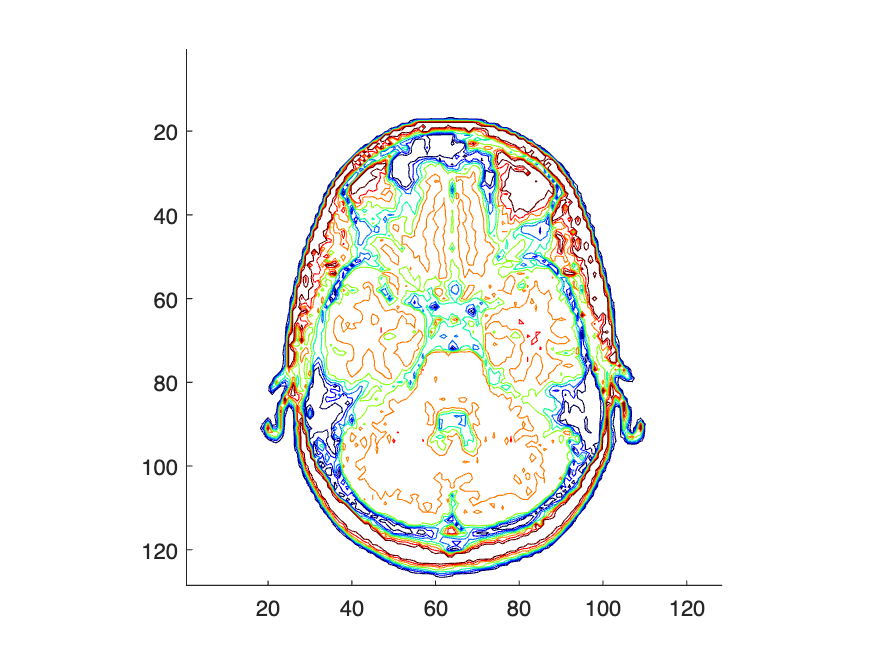


x = xlim;
y = ylim;

cm = brighten(jet(length(map)),-.5);
figure
colormap(cm)
contourslice(D,[],[],image_num)
axis ij
xlim(x)
ylim(y)
daspect([1,1,1])

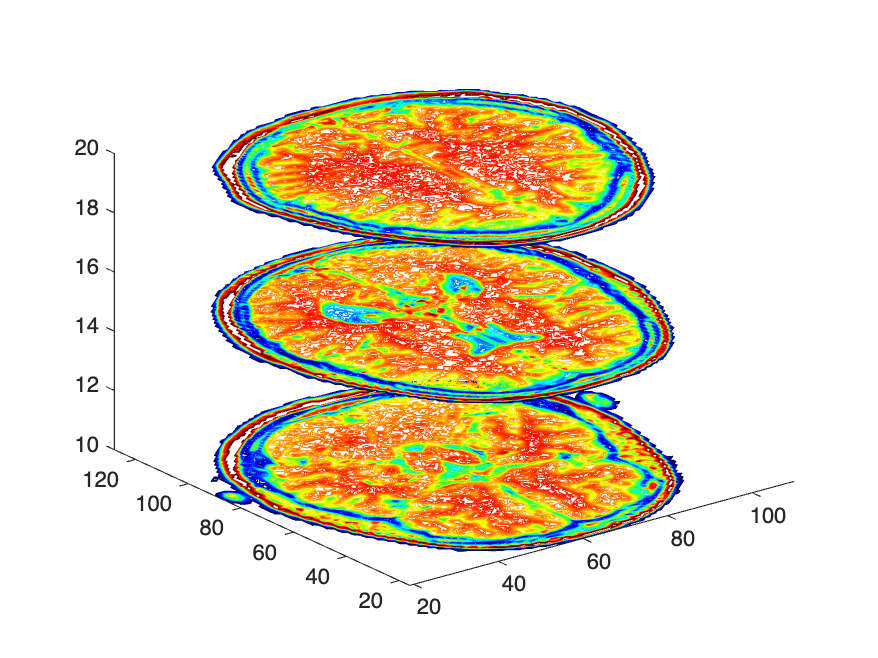


figure
colormap(cm)
contourslice(D,[],[],[10 15 20],75);
view(3);
axis tight

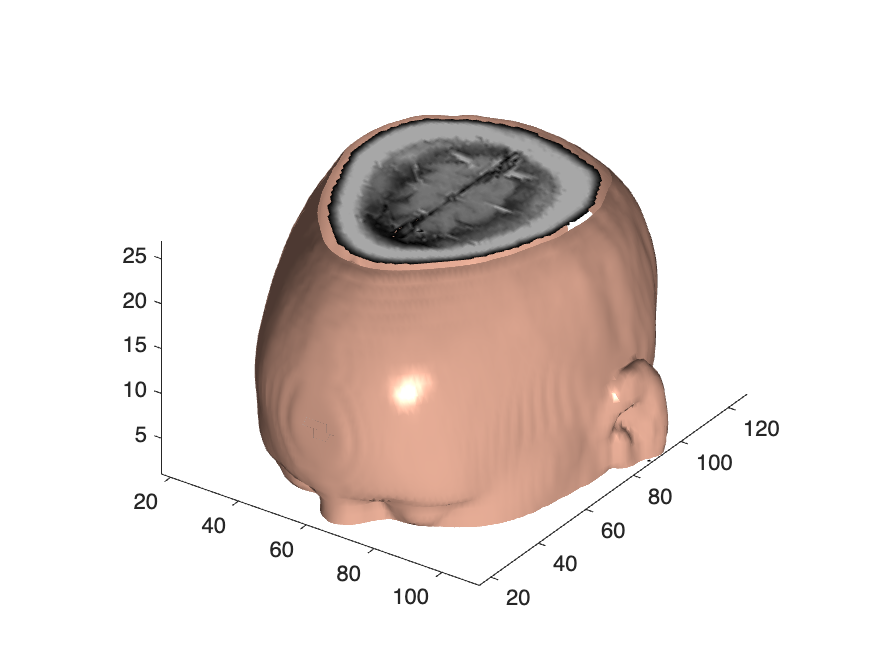


figure
colormap(map)
Ds = smooth3(D);
hiso = patch(isosurface(Ds,5),...
   'FaceColor',[1,.75,.65],...
   'EdgeColor','none');
   isonormals(Ds,hiso)

hcap = patch(isocaps(D,5),...
   'FaceColor','interp',...
   'EdgeColor','none');

view(35,30) 
axis tight 
daspect([1,1,.4])

lightangle(45,30);
lighting gouraud
hcap.AmbientStrength = 0.6;
hiso.SpecularColorReflectance = 0;
hiso.SpecularExponent = 50;